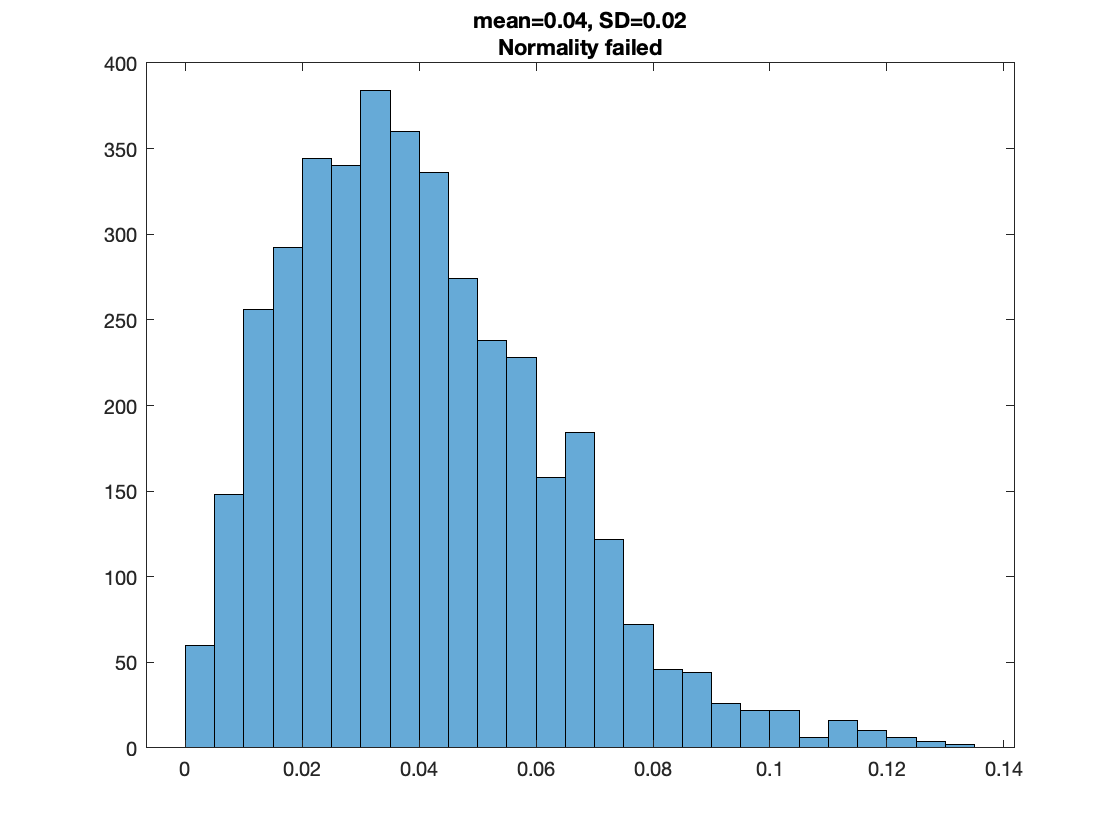

figure,
iORI = 12;
iSF = 28;

e3D = energy2D_allT_perComb;
e_bin_fix = squeeze(e3D(:, iORI, iSF));

histogram(e_bin_fix)
if swtest(e_bin_fix) == 1, title_ = 'Normality failed';
else, title_ = 'Normality confirmed';
end
title(sprintf('mean=%.2f, SD=%.2f\n%s', mean(e_bin_fix), std(e_bin_fix), title_))